Abdullah Ahmed

aa09303

Lab -2

**Task 1**

a = complex(15.5, 3.175);
[xb, yb] = pol2cart(deg2rad(45), 5);
b = complex(xb, yb);

% a)
real(a)

ans = 15.5000

real(b)

ans = 3.5355


% b)
imag(a)

ans = 3.1750

imag(b)

ans = 3.5355


% c)
conj(a)

ans = 15.5000 - 3.1750i

conj(b)

ans = 3.5355 - 3.5355i


% d)
angle(a)

ans = 0.2020

angle(b)

ans = 0.7854


% e)
abs(a)

ans = 15.8218

abs(b)

ans = 5

**Try 1**

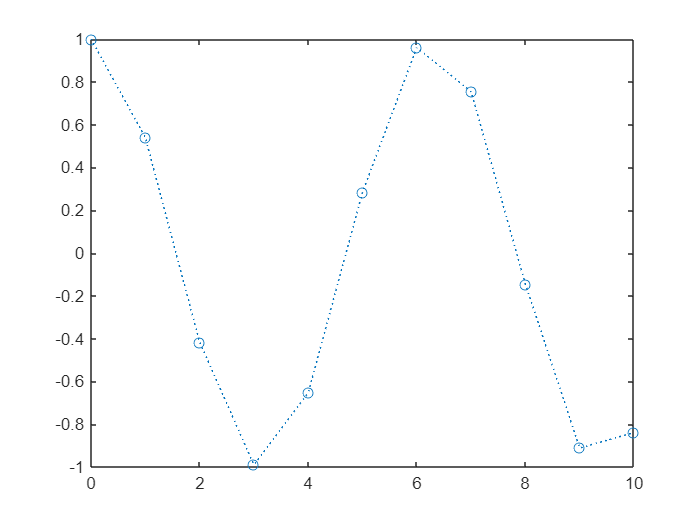

n = 0:10;
y = cos(n);

figure;
plot(n, y, ':o');

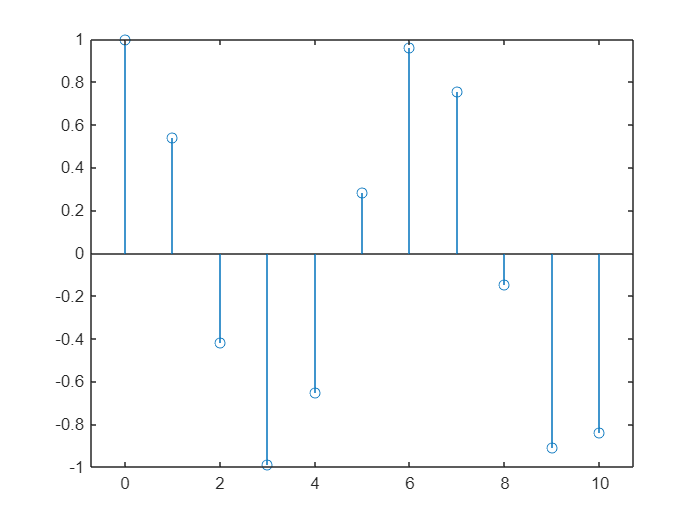

figure;
stem(n, y);

**Try 2**

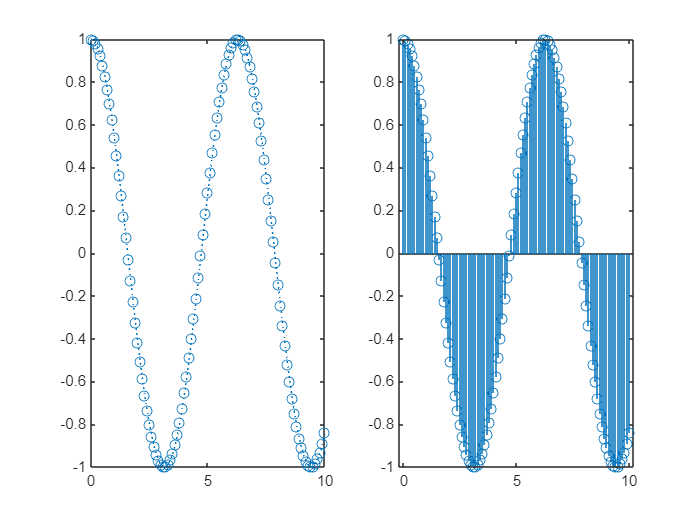

Ts = 0.1; 
t = 0:Ts:10;
y = cos(t);

figure;
subplot 121;
plot(t, y, ':o');

subplot 122;
stem(t, y);

**Task 2 (a)**

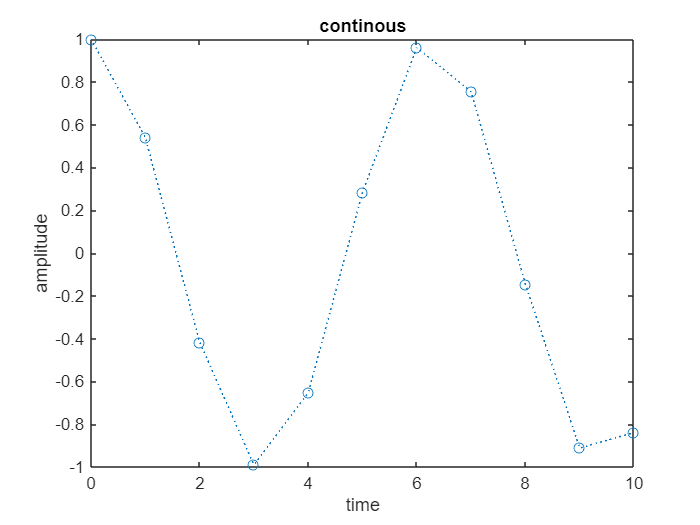

n = 0:10;
y = cos(n);

figure;
plot(n, y, ':o');
title("continous");
xlabel("time");
ylabel("amplitude");

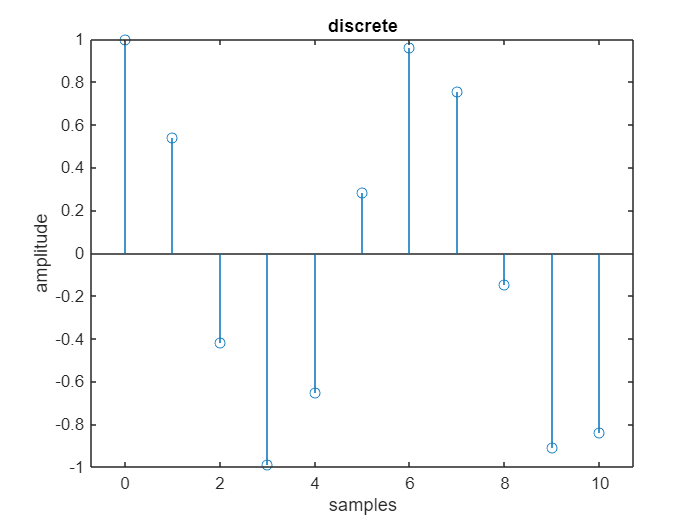


figure;
stem(n, y);
title("discrete");
xlabel("samples");
ylabel("amplitude");

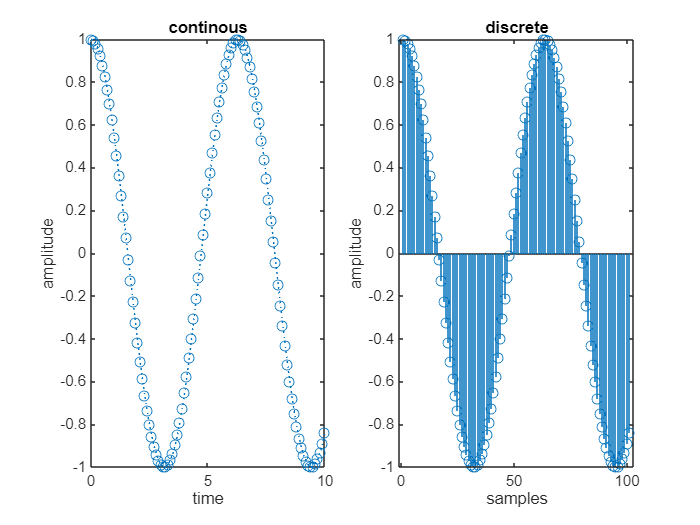


Ts = 0.1; 
Fs = 1/Ts;
t = 0:Ts:10;
n=1:length(t);
y = cos(t);

figure;
subplot 121;
plot(t, y, ':o');
title("continous");
xlabel("time");
ylabel("amplitude");

subplot 122;
stem(n, y);
title("discrete");
xlabel("samples");
ylabel("amplitude");

**Task 2 (b)**

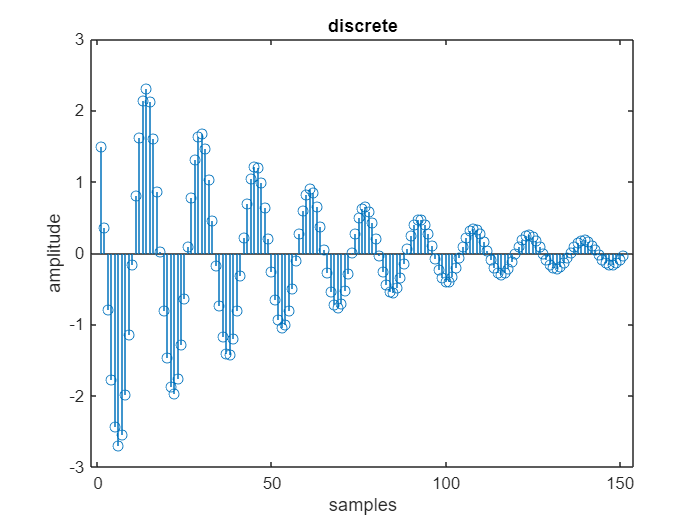

fs = 50;
ts = 1/fs;
t = 0:ts:3;
func = 3 * exp(-t) .* cos(20 * t + pi / 3);
figure;
stem(1:length(t), func);
title("discrete");
xlabel("samples");
ylabel("amplitude");

**Try 3**

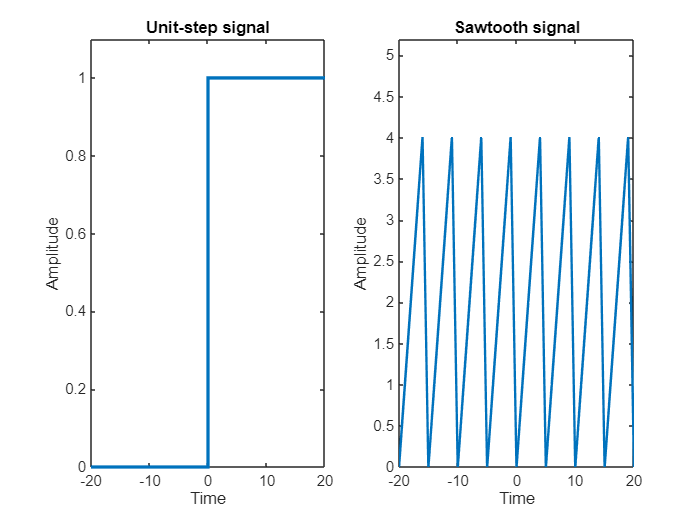

clc; clear
t = -20:1:20;
y = mod(t,5); % equivalent to t % 5
z = t>=0; % 0 for t<0, 1 for t >= 0

subplot(1,2,1); % a subplot of 1 row and 2 columns
stairs(t,z,'linewidth',2);
title('Unit-step signal');
xlabel('Time');
ylabel('Amplitude');
axis([-20 20 0 1.1]); % [min_x, max_x, min_y, max_y]

subplot(1,2,2);
plot(t,y,'linewidth',1.5);
title('Sawtooth signal');
xlabel('Time');
ylabel('Amplitude');
axis([-20 20 0 5.2]); % [min_x, max_x, min_y, max_y]

**Task 3**

t = -20:0.1:20;
y = sawtooth(t, 0); % bultin function for unit sawtooth
z = (t>=0) % 0 for t<0, 1 otherwise

z = 1×401 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


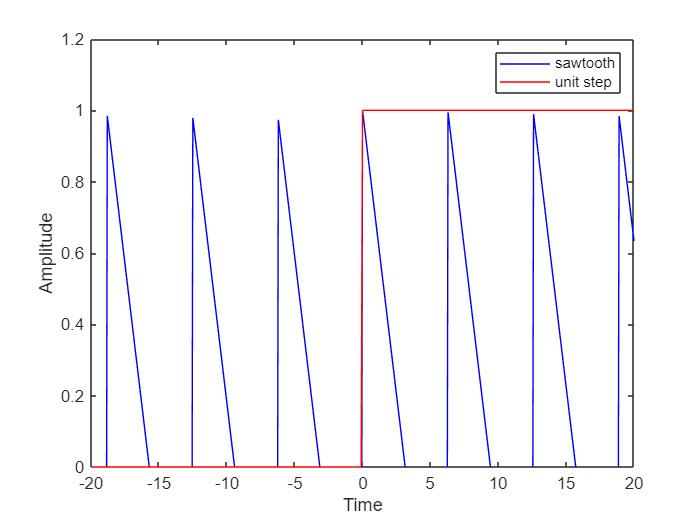


figure
plot(t, y, "blue");
hold on; % to plot boht signals on one figure
plot(t, z, "red");
xlabel('Time');
ylabel('Amplitude');
axis([-20 20 0 1.2]); % [min_x, max_x, min_y, max_y]
legend("sawtooth", "unit step");

**Task 4**

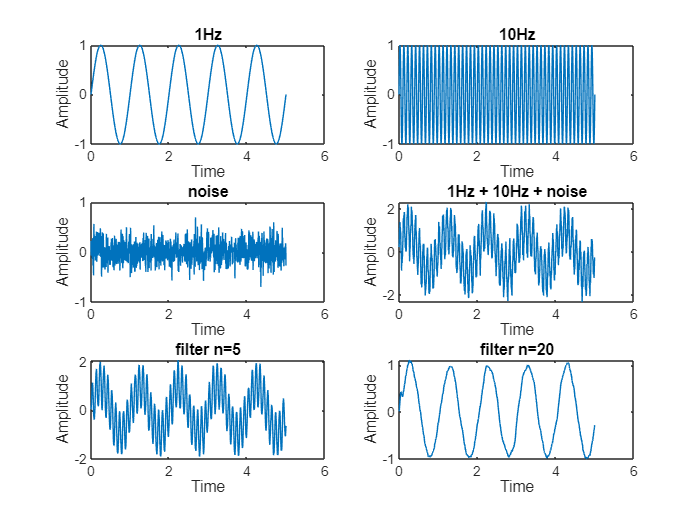

t = 0:0.005:5;
f1 = 1;
f2 = 10;
xt1 = sin(2*pi*f1*t);
xt2 = sin(2*pi*f2*t);
noise = 0.2 * randn(size(t));

yt = xt1 + xt2 + noise;
zt1 = filter(ones(1,5)/5 , 1, yt);
zt2 = filter(ones(1,20)/20 , 1, yt);

subplot 321;
plot(t, xt1);
title("1Hz")
xlabel('Time');
ylabel('Amplitude');

subplot 322;
plot(t, xt2);
title("10Hz")
xlabel('Time');
ylabel('Amplitude');

subplot 323;
plot(t, noise);
title("noise")
xlabel('Time');
ylabel('Amplitude');

subplot 324;
plot(t, yt);
title("1Hz + 10Hz + noise")
xlabel('Time');
ylabel('Amplitude');

subplot 325;
plot(t, zt1);
title("filter n=5")
xlabel('Time');
ylabel('Amplitude');

subplot 326;
plot(t, zt2);
title("filter n=20")
xlabel('Time');
ylabel('Amplitude');

Applying a moving average filter with n=5 reduces some noise but retains the 10Hz component, resulting in partial smoothing. In contrast, a filter with n=20 significantly suppresses high-frequency components and noise, leaving primarily the 1Hz wave. This shows that a larger filter window provides better noise reduction and emphasizes low-frequency components, effectively acting as a low-pass filter.

## **                                <--------  Post Lab  ---------->**

**Task 5**

1 a)

a = complex(10.09, 55.3);
[b_r, b_i] = pol2cart(deg2rad(85.5) , 20)

b_r = 1.5692

b_i = 19.9383

b = complex(b_r, b_i);
x = a + b;

real(x)

ans = 11.6592

imag(x)

ans = 75.2383

conj(x)

ans = 11.6592 -75.2383i

angle(x)

ans = 1.4171

abs(x)

ans = 76.1364

1 b)

[a_r, a_i] = pol2cart(deg2rad(10), 15);
y = complex(a_r, a_i) + complex(-4, 10);
real(y)

ans = 10.7721

imag(y)

ans = 12.6047

conj(y)

ans = 10.7721 -12.6047i

angle(y)

ans = 0.8636

abs(y)

ans = 16.5806

2)

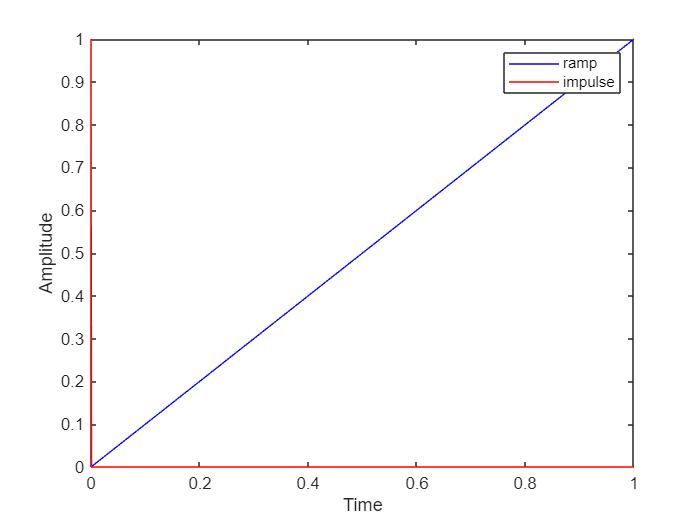

t = 0:0.001:1;
ramp = t;
impulse = (t == 0);

figure;
plot(t, ramp, "blue");
hold on;
plot(t, impulse, "red");
xlabel('Time');
ylabel('Amplitude');
legend("ramp", "impulse");

**Task 6**

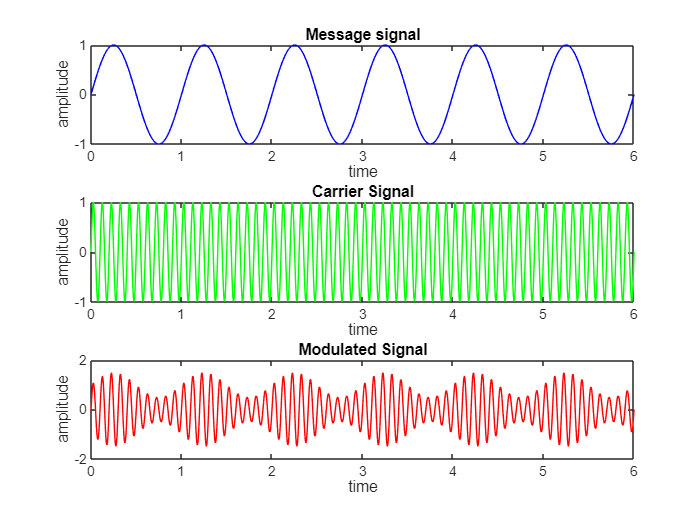

t = 0:1/150:6;
mt = sin(2 * pi * t);
ct = sin(2 * pi * 10 * t);
ft = (1 + 0.5 * mt) .* ct;

figure;

subplot 311;
plot(t, mt, "blue");
title("Message signal");
xlabel("time");
ylabel("amplitude");

subplot 312;
plot(t, ct, "green");
title("Carrier Signal");
xlabel("time");
ylabel("amplitude");

subplot 313;
plot(t, ft, "red");
title("Modulated Signal");
xlabel("time");
ylabel("amplitude");